Math 155 Final Project Test

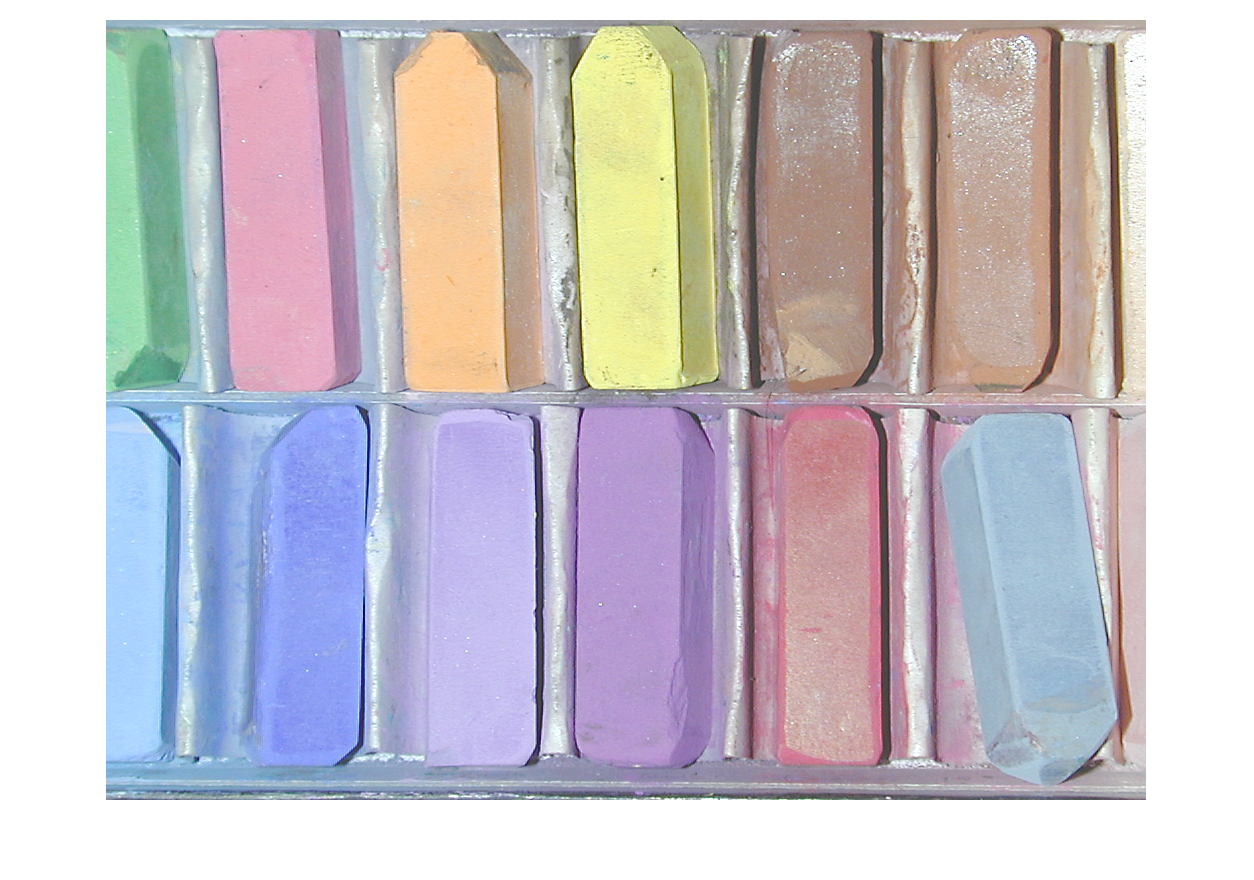

clear;clc;close all;
rgb_img = imread("rgb_img.tif");
rgb_img = imresize(rgb_img,[780 1040]);
imshow(rgb_img)

% set mosaic size as scaled down from original image
scaling_factor = 10; % can change
[img_rows, img_cols, rgb_index] = size(rgb_img);
mosaic_rows = floor(img_rows/scaling_factor); % number of tiles across in mosaic
mosaic_cols = floor(img_cols/scaling_factor); % number of tiles down in mosaic

% split image into tiles that will be replaced with images later
cell_img = cell(mosaic_rows, mosaic_cols); % cell array whose entries are the tiles of the image
for i=0:mosaic_rows-1
    for j=0:mosaic_cols-1
        cell_img{i+1,j+1} = rgb_img((i*scaling_factor+1):(i+1)*scaling_factor,(j*scaling_factor+1):(j+1)*scaling_factor,:);
    end
end

% get average rgb intensity values for each orignal image tile
avg_rgb = zeros(mosaic_rows, mosaic_cols, 3);
for i=1:mosaic_rows
    for j=1:mosaic_cols
        current_tile = cell_img{i,j};
        for rgb = 1:3
            avg_rgb(i,j,rgb) = mean(mean(current_tile(:,:,rgb)));
        end
    end
end

% import images
% I just used the ones from the example to make things easier at first
% we can use other images if we want
listing = dir(['flowerTiles' '/*.' 'png']);
for i = 1:500
    imageName = listing(i).name;
    tiles{i} = imread(['flowerTiles' '/' imageName],'png');
end

% compute average rgb values for tiles
avg_tiles = zeros(500,3);
for i=1:500
    current_tile = tiles{i};
    for rgb_index = 1:3
        avg_tiles(i,rgb_index) = mean(mean(current_tile(:,:,rgb_index)));
    end
end

% find best fit image for each tile on grid
mosaic = cell(mosaic_rows,mosaic_cols);
for i=1:mosaic_rows
    for j=1:mosaic_cols
        min_dist = 100000;
        best_image = 0;
        for k = 1:500
            dist = sqrt( ( avg_rgb(i,j,1) - avg_tiles(k,1))^2 + ( avg_rgb(i,j,2) - avg_tiles(k,2))^2 + ( avg_rgb(i,j,3) - avg_tiles(k,3))^2 );
            if dist < min_dist
                min_dist = dist;
                best_image = k;
            end
        end
        % save best image into cell array
        mosaic{i,j} = tiles{best_image};
    end
end

% construct mosaic
final_mosaic = cell2mat(mosaic);

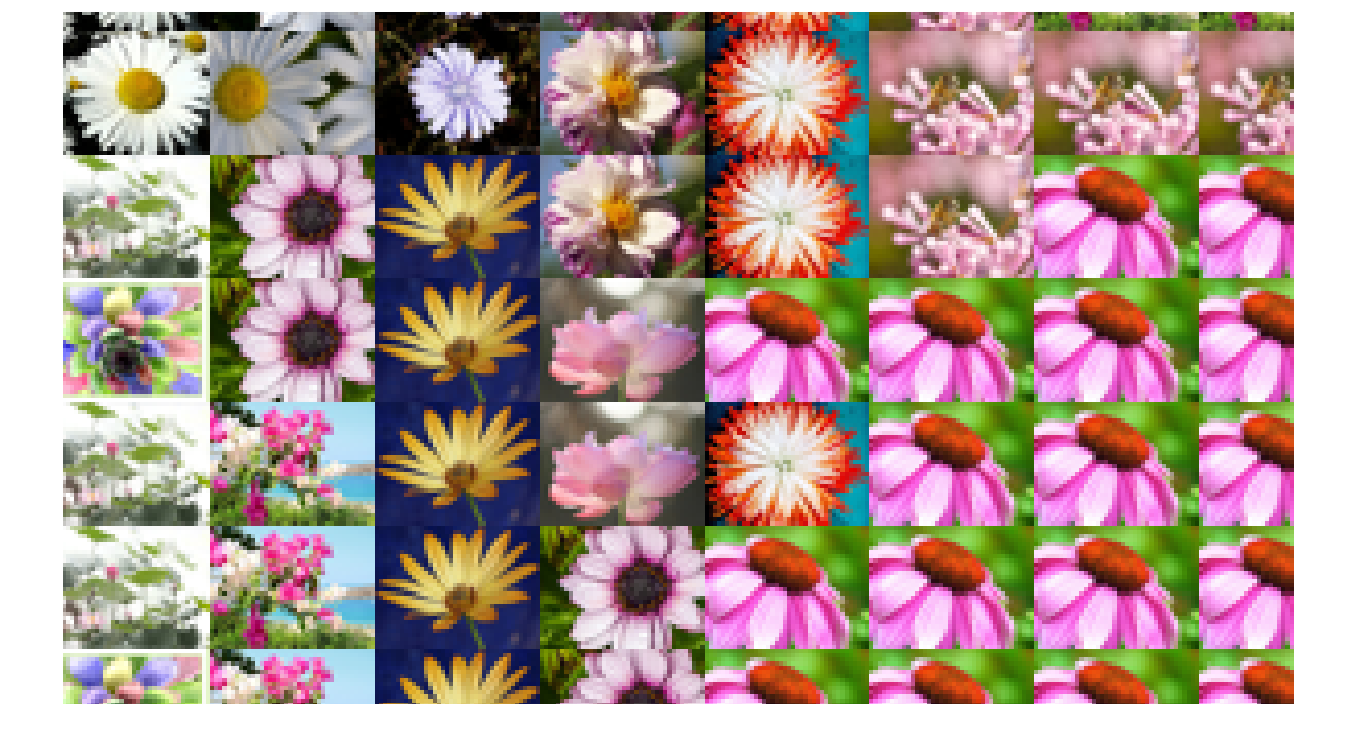

imshow(final_mosaic)